# **Seguimiento N°9**

## **Modelo Neoclásico de Crecimiento**

**Teoría Macroeconómica I**

**Profesor: Alexandre Janiak      Ayudantes:  Pablo Vega y Bianca Hincapié**

**Estudiante: Valentina Andrade de la Horra**

Para el análisis consideraremos una economía cerrada que evoluciona en tiempo discreto. Supondremos que en esta economía se produce un solo bien, el cual puede ser consumido o invertido. El hogar representativo obtiene un flujo de utilidad $u\left(c\right)$ por consumir $c$ y descuenta el futuro a un factor $\beta$. El bien y es producido mediante una tecnología $e^z \cdot f\left(k\right)$ donde $e^z$ denota la productividad total de factores y k el stock de capital al comienzo del periodo, el cual se deprecia a una tasa $\delta$.

-  Compute las funciones de politíca de capital y consumo asumiendo que el nivel de productividad de la economía está dado por (1), con $\rho =0\ldotp 97$ y  $\sigma_{\varepsilon } =0\ldotp 0072$. Para cada nivel de productividad, indique:

-  ¿El capital converge al estado estacionario? 

- ¿Cuál es su velocidad de convergencia? ¿Es localmente estable? Explique.

clear variables; close all; clc
%----------------------
% Parameters
%----------------------
sigma= 1; 
beta= .984; 
delta=.025;  alpha=1/3;
rho= 0.97;  sde= .0072;

% Grid points (variables de estado)
nz= 3; % Productivity (3 niveles de tfp)
nk= 21;% Kapital (acotamos el capital)

% Utility function
utility= @(c)  crra(c, sigma);

% Transition matrix
[zg,Pi]= tauchen(rho,sde,3,nz);
% Productivity grid
zg= exp(zg');  
nz= length(zg);

% Capital SS
Kss= @(z) (z*alpha/(1/beta-(1-delta)))^(1/(1-alpha)); 

% Capital bounds (se evalua en 1 este es nuestro SS deterministico)
kss= Kss(1);

% Capital grid (discretizamos la grilla en torno al Kss)
kmin= 0.2*kss; % cota inferior de la grilla 20% de Kss) 
kmax= 1.4*kss; % cota superior de la grilla 40% mas que Kss)
kg= linspace(kmin,kmax,nk);
nk= length(kg);

%----------------------
% VFI
%----------------------
tol= 1e-4;  maxiter= 1000;  showiter= 20;

% Preallocation
v0= zeros(nz,nk);   %value function
kpf= zeros(nz,nk);  %Policy capital 

% Initialization
err= 1;  
iter= 0;
v1= zeros(nz,nk); % Guess Value inicial

tic
% Value function iteration
while err>tol
    
    % Continuation value: E[ V1 |z ]
    Ev1= Pi*v1; % matriz de 3 (estados de prodc) x 21 niveles de k
    
    % Loop over productivity
    for iz= 1:nz
            
        % Piecewise polinomial: spline on E[ V1 |z=zi ]
        vpp= spline(kg, Ev1(iz,:)); % aproximacion cubica dados los niveles 
        %Kss min y Kss max le das un nivel k y busca una aprox de la
        %funcion de valor, la cuales convada (como la f, de util)
        %vpp es una estructura de matlab que contiene distintos data frame

        % Loop over capital
        for ik= 1:nk % nz=3 niveles de productividad
            % Objective for minimization (el vaux se pone negativo)
            obj= @(kp)  -vaux(zg(iz),kg(ik),kp, ...
                                beta,delta,alpha,utility,vpp);
                            
            % k' bounds % (4) c = e^z*k^alpha -k'-(1-delta)k, supondiendo
            % c=0, obtengo: (5) k'= e^z*k^alpha+(1-delta)k => quetemos que
            % itere sobre valores donde c>=0
            kub= min(kmax, zg(iz)*kg(ik)^alpha + (1-delta)*kg(ik)); % eq (5)
            % kub son los valores max de esta iter que cumple con propiedad
            % c>=0
            % Policy function: max k' over [klb,kub]
            [kpf(iz,ik),vneg]=  fminbnd(obj,kmin,kub); %como es -vaux se cumple
            % Value function
            v0(iz,ik)= -vneg; %lo multplicamos por - porque sabemos que es un max
        end
    end
    
    % Norm
    err= max(max(abs(v0-v1)));
    % Value update
    v1= v0;
    
    % Iterations
    iter= iter+1;
    if (iter>maxiter), break; end
    % Display
    if mod(iter,showiter)==0
        fprintf('err: %.2e  |  iter: %d \n',[err,iter]);
    end
end

err: 6.76e-01  |  iter: 20 
err: 4.58e-01  |  iter: 40 
err: 3.27e-01  |  iter: 60 
err: 2.36e-01  |  iter: 80 
err: 1.70e-01  |  iter: 100 
err: 1.23e-01  |  iter: 120 
err: 8.93e-02  |  iter: 140 
err: 6.47e-02  |  iter: 160 
err: 4.68e-02  |  iter: 180 
err: 3.39e-02  |  iter: 200 
err: 2.46e-02  |  iter: 220 
err: 1.78e-02  |  iter: 240 
err: 1.29e-02  |  iter: 260 
err: 9.34e-03  |  iter: 280 
err: 6.76e-03  |  iter: 300 
err: 4.90e-03  |  iter: 320 
err: 3.55e-03  |  iter: 340 
err: 2.57e-03  |  iter: 360 
err: 1.86e-03  |  iter: 380 
err: 1.35e-03  |  iter: 400 
err: 9.76e-04  |  iter: 420 
err: 7.07e-04  |  iter: 440 
err: 5.12e-04  |  iter: 460 
err: 3.71e-04  |  iter: 480 
err: 2.69e-04  |  iter: 500 
err: 1.95e-04  |  iter: 520 
err: 1.41e-04  |  iter: 540 
err: 1.02e-04  |  iter: 560 


toc

Elapsed time is 12.486512 seconds.


% Output message
if (iter<maxiter)
    fprintf('VF converged:  %.2e  |  iter: %d \n',[err,iter])
else
    warning('Error: Iterations exceeded')
end

VF converged:  9.88e-05  |  iter: 562 


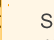


% Consumption policy
cpf= zg*kg.^alpha + (1-delta)*kg  - kpf;

tx= {'Interpreter','Latex'};

figure(1);
% Capital policy
hold on
plot( kg, kg, 'Linestyle',':','color','k')
plot( kg, kpf);
hold off
title('Policy function Capital')
xlabel('$k$', tx{:}); ylabel("$k^\prime$", tx{:})
legend('45°','policy del capital' ,'Location','SE')
saveas(gcf,'figure1.png')

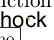


% Consumption policy
figure(2)
plot( kg, cpf);
title('Policy function Consumo')
xlabel('$k$', tx{:}); ylabel("$c$", tx{:})
legend('policy de consumo' ,'Location','SE')
saveas(gcf,'figure2.png')

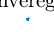


%
%----------------------
% Stochastic SS
%----------------------
% Periods
Tsss= 500;

% Deterministic SS
isss= 2;

% Capital path
kt= zeros(1,Tsss);
kt(1)= Kss(1); % comenzamos con el nivel de Kss estimado antes

for it= 2:Tsss
   kt(it)= interp1(kg, kpf(isss,:) , kt(it-1)); % interpolacion lineal
   % input la kg = grilla
end

% Stochastic SS
ksss= kt(end);
csss= interp1(kg, cpf(isss,:) , ksss );
ysss= zg(isss)*ksss^alpha; % el producto es la funcion de produccion y=e^z*k^alpha
invsss= ysss - csss;

figure(3)
plot(1:Tsss, kt)
title('Velocidad de Converegencia del Capital')
xlabel('$T$', tx{:}); ylabel("$k^{*}$", tx{:})
saveas(gcf,'figure3.png')

2. Considere un shock que aumenta en un 1% el stock de capital. Compute la convergencia al estado estacionario e interprete las trayectorias. 

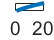

%----------------------
% Capital shock
%----------------------
T= 80; %computamos para 80 periodos
tg= 1:T;

% Preallocation
kt= zeros(1,T+1);  
ct= zeros(1,T);  
yt= ct;  
invt= ct;

% Initial conditions
kt(1)= ksss*1.01; % el Kss se multiplica por 1.01 porque es un shock positivo de 1%

% path
for it= 1:T
   % Consumption
   plot(cpf(isss,:))
   ct(it)= interp1(kg,cpf(isss,:),kt(it));
   % Output
   yt(it)= zg(isss)*kt(it)^alpha;
   % Investment
   invt(it)= yt(it) - ct(it);
   % Capital
   kt(it+1)= interp1(kg, kpf(isss,:) , kt(it) );
end

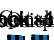


%----------------------
% Plots
%----------------------
figure(4);
% Capital path
subplot(2,2,1)
hold on
plot( 1:T+1, kt);
plot( [1 T+1], [ksss ksss], 'Linestyle',':','color','k')
hold off
title('Capital')
% Consumption path
subplot(2,2,2)
hold on
plot( 1:T, ct);
plot( [1 T], [csss csss], 'Linestyle',':','color','k')
hold off
title('Consumo')
% Investment
subplot(2,2,3)
hold on
plot( 1:T, invt);
plot( [1 T], [invsss invsss], 'Linestyle',':','color','k')
hold off
title('Inversion')
% Output
subplot(2,2,4)
hold on
plot( 1:T, yt);
plot( [1 T], [ysss ysss], 'Linestyle',':','color','k')
hold off
title('Output')
saveas(gcf,'figure4.png')

3.  Considere un shock negativo a la TFP de magnitud 1%, obtenga las IRF y entregue una interpretación económica. 

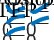

%----------------------
% IRF: persistent shock
%----------------------
% NOTE: use the appropiate quadrature.

% Preallocation
kt= zeros(1,T+1);
ct= zeros(1,T);  
yt= ct;  
invt= ct;

% Productivity path
zt= zg(isss)*ones(1,T+1);

% Purely transitory shock
zt(1)= zg(isss)*0.99; % se multiplica por 0.99 por que es 
% un shock negativo de 1%

% Initial conditions
kt(1)= ksss;
% Time path
for it= 1:T
   % Consumption
   ct(it)= interp2(kg,zg,cpf,kt(it),zt(it));
   % Output
   yt(it)= zt(it)*kt(it)^alpha;
   % Investment
   invt(it)= yt(it) - ct(it);
   % Capital
   kt(it+1)= interp2(kg,zg, kpf, kt(it),zt(it) );
   % Productivity
   zt(it+1)= exp( rho*log(zt(it)) ); %e^{z_t}
end

% Percentage deviation
khat= log(kt(2:end))-log(ksss);
chat= log(ct(2:end))-log(csss);
yhat= log(yt(2:end))-log(ysss);
invhat= log(invt(2:end))-log(invsss);
zhat= log(zt(2:end))-log(zt(end));

%----------------------
% Plots
%----------------------

figure(5);
% Capital path
subplot(3,2,1)
hold on
plot( 1:T, khat);
hold off
title('Capital')
% Consumption path
subplot(3,2,2)
hold on
plot( 1:T-1, chat);
hold off
title('Consumo')
% Investment
subplot(3,2,3)
hold on
plot( 1:T-1, invhat);
hold off
title('Inversion')
% Output
subplot(3,2,4)
hold on
plot( 1:T-1, yhat);
hold off
title('Output')
% Productivity
subplot(3,2,5)
hold on
plot( 1:T, zhat);
hold off
title('TFP')
saveas(gcf,'figure5.png')